# Inicia TODO el CoBot

%%Iniciamos la configuracion de cobot
[jointSub,trajGoal,gripGoal,trajAct,gripAct,~,rgbImgSub,rgbDptSub] = iniciarconexionRos() %Iniciamos todo, debemos de verificar la direccion ip en la funcion

Shutting down global node /matlab_global_node_71727 with NodeURI http://atorony-pc:33093/ and MasterURI http://172.17.0.1:11311.
Initializing global node /matlab_global_node_32847 with NodeURI http://atorony-pc:41957/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updat

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: [1×1 JointState]
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'object'


trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


trajAct =   SimpleActionClient with properties:

           ActionName: '/pos_joint_traj_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 1
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: []
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


gripAct =   SimpleActionClient with properties:

           ActionName: '/gripper_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 1
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: []
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


rgbImgSub =   Subscriber with properties:

                      TopicName: '/camera/rgb/image_raw'
                  LatestMessage: [1×1 struct]
                    MessageType: 'sensor_msgs/Image'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'


rgbDptSub =   Subscriber with properties:

                      TopicName: '/camera/depth/image_raw'
                  LatestMessage: [1×1 struct]
                    MessageType: 'sensor_msgs/Image'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'


[RobotConfiguration,jointStateMsg] = ConfigurarRobot(jointSub) %Hacemos el setup de las cosas del cobot

RobotConfiguration = 1×6 struct array with fields:
    JointName
    JointPosition


jointStateMsg =     0.5000
    0.5000
    3.0000
    3.0000
    0.5000
    0.5000


defase_Robot = -pi/2;

# Mover al cobot por coordenadas cartesianas

x = 0.2968;
y = 0.6146

y = 0.6146

z = -0.095+.3;
angulo_Gripper = 90;

coci = car2pol(x,y,z)

coci =     0.6825    1.1209    0.2050


RobotConfiguration = MoverRobot(coci,angulo_Gripper,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub);

# Movimiento Manual del Cobot

%Limites de los sliders
theta_min = -3*pi/4;
theta_max = 3*pi/4;
angulogripmin = -pi;
angulogripmax = pi;

r =0.25

r = 0.2500

theta = 0

theta = 0

h_deseada = 0.275

h_deseada = 0.2750

angulo_Gripper = 0

angulo_Gripper = 0


h_posible = min(h_deseada,sqrt(0.91^2-r^2)) 

h_posible = 0.2750

% coordenadas_cilindricas(r,theta,h)
coci = [r,theta,h_posible];

RobotConfiguration = MoverRobot(coci,angulo_Gripper,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub);

# Control de gripper

%%%Damos valor de abierto o cerrado al gripper 0 abieto, 0.8 cerrado
% 0 abierto, 0.8 cerrado
gripPos = 0

gripPos = 0

gripper(gripAct,gripGoal,gripPos,jointSub)

ans =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


# %%%%%%%%%%---FUNCIONES DE MOVIMIENTO---%%%%%%%%%%

# Mandamos a posicion inicial

%%%Mandamos al robot a su posicion inicial
inicial(RobotConfiguration,trajGoal,trajAct)

# Mandamos a la bascula

presion = 0.5;
RobotConfiguration = bascula(coci,presion,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub,gripAct,gripGoal,angulo_Gripper)

# Mandamos al bote Azul (0) o Verde (1) 

cesto = 1

cesto = 1

RobotConfiguration = bote(coci,angulo_Gripper,cesto,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub,gripAct,gripGoal)

RobotConfiguration = 1×6 struct array with fields:
    JointName
    JointPosition


# %%%%%%%%%%---FUNCIONES DE TABLAS---%%%%%%%%%%

# Crear tabla

% Crear una tabla vacía con las etiquetas especificadas
columnas = {'Objeto', 'Etiqueta', 'X', 'Y', 'Z', 'Angulo_gripper', 'Cesto', 'Grippos'};

% Crear una tabla con tipos de datos predefinidos
TablaDatos = table([],string([]), [], [], [], [], [], [], 'VariableNames', columnas);

# Agregar datos a la tabla

numerodeobjeto = TablaDatos.Objeto(numerodeobjeto)+1;
zeta = h_posible;
angulo_gripper = 0;
cesto_debasura = 1;
cierre_gripper = gripPos;

nueva_fila = {numerodeobjeto,'Lata',x,y,zeta,angulo_gripper,cesto_debasura,cierre_gripper};
TablaDatos = [TablaDatos; nueva_fila];

% Mostrar la tabla
disp(TablaDatos);

% Borra todas las filas y mantiene la estructura
TablaDatos = TablaDatos([],:);

% Elimina la n fila en este caso
TablaDatos(5,:) = [];
%n=n-1;

% Guarda la tabla en un archivo MAT
save('mi_tabla.mat','TablaDatos');

% Carga la tabla desde el archivo MAT
load('mi_tabla.mat','TablaDatos');

# %%%%%%%%%%---FUNCIONES DE CAMARAS---%%%%%%%%%%

# Camara color

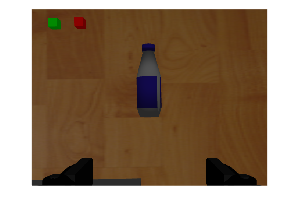

%%%Tomamos una foto a color
rgbImg = imgcolor(rgbImgSub);

imwrite(rgbImg,"botella.png")

# Cámara profundidad

%%%Tomamos una foto de la profundidad
imgprf = imgprof(rgbDptSub)

# %%%%%%%%%%---PRESIONES EN OBJETOS---%%%%%%%%%%

# Presiones sobre objetos

Tapas de botellas = 0.515

Cuerpo de botellas = 0.21

Tapa de lata = 0.23

Cuerpo de lata = 0.23

Cubitos = 0.64

Plumon = 0.655

SPAM = 0.425

# %%%%%%%%%%---PRUEBAS---%%%%%%%%%%

# Funcion de prueba en (altura)

%0.1 - 0.7 en x ;
%Mano hacia adentro o mano hacia afuera
for h = 0.5:-0.1:0
theta = 0;
r = 0.5
% coordenadas_cilindricas(r,theta,h)
coci = [r,theta,h];

% ángulo de ajuste de griper a partir de la posición radial
angulo_Gripper = 0;

%Se envia la transformacion homogenea

RobotConfiguration = MoverRobot(coci,angulo_Gripper,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub)
end

# Funcion de prueba de barrido (r,theta)

%%Prueba de rutina de movimiento lineal
% ángulo de ajuste para la rotación del robot
n = -1;
for r = 0.25:0.2:0.85
    n=n+1;
    for theta = -3*pi/4:pi/(2+n):3*pi/4
        h_deseada = 0.3;
        h_posible = min(h_deseada,sqrt(0.86^2-r^2)) 
        % coordenadas_cilindricas(r,theta,h)
        coci = [r,(-1)^n*theta,h_posible];

        % ángulo de ajuste de griper a partir de la posición radial
        angulo_Gripper = 0;

        %Se envia la transformacion homogenea

        RobotConfiguration = MoverRobot(coci,angulo_Gripper,defase_Robot,RobotConfiguration,trajGoal,trajAct,jointSub);
    end
end